close all;
clear all;

clock_freq = 1e8;
limits = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 18, 20, 24, 28, 35, 45, 60, 75, 100, 125, 150, 175, 200];
time = limits.*(1e6/clock_freq);

model = "basys";

## TERO-4

prefix = "tero_4_equality_raw";

equalities_tero_4 = zeros(1, length(limits));
data = readmatrix(model+"_"+prefix+'_'+string(limits(length(limits)))+'.csv');
[size_sample_tero_4, size_response_tero_4] = size(data);

for i=1:length(limits)
    data = readmatrix(model+"_"+prefix+'_'+string(limits(i))+'.csv');
    equalities_tero_4(i) = mean(sum(data,2)/size_response_tero_4)*100;
end

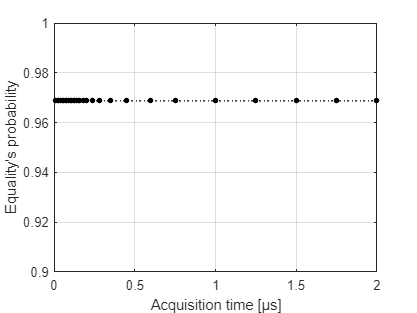

fig_tero_4 = figure;
p = plot(time, equalities_tero_4./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
grid on;
xlabel("Acquisition time [µs]");
ylabel("Equalities");
ylim([0.9 1]);

## TERO-8

prefix = "tero_8_equality_raw";

equalities_tero_8 = zeros(1, length(limits));
data = readmatrix(model+"_"+prefix+'_'+string(limits(length(limits)))+'.csv');
[size_sample_tero_8, size_response_tero_8] = size(data);

for i=1:length(limits)
    data = readmatrix(model+"_"+prefix+'_'+string(limits(i))+'.csv');
    equalities_tero_8(i) = mean(sum(data,2)/size_response_tero_8)*100;
end

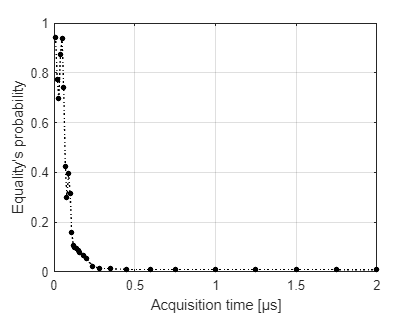

fig_tero_8 = figure;
p = plot(time, equalities_tero_8./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
grid on;
xlabel("Acquisition time [µs]");
ylabel("Equalities");

## Both

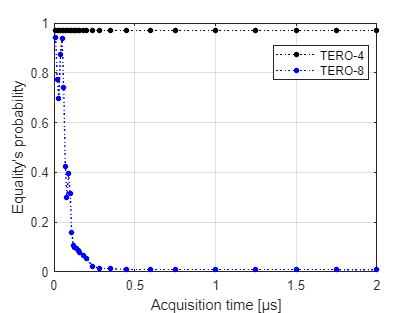

fig_both = figure;
p = plot(time, equalities_tero_4./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
p = plot(time, equalities_tero_8./100, ':.');hold on;
p.Color = 'blue';
p.MarkerFaceColor = 'blue';
p.MarkerSize = 12;
grid on;
xlabel("Acquisition time [µs]");
ylabel("Equalities");
legend("TERO-4","TERO-8");

legend("Position", [0.65732,0.74714,0.2243,0.10748])

saveas(fig_tero_4, "tero_4_oscillations_equality.png");

saveas(fig_tero_8, "tero_8_oscillations_equality.png");

saveas(fig_both, "all_oscillations_equality.png");